# Computer Assignment #1

## Ali Hamzehpour 810100129

### Part one

#### 1-1

    In this part we simply run a MATLAB script to figure out how some basic functions and operations work. First we define an array which represents  the domain of the function. The array consists of numbers from 0 to 1 with step 0.01. After that we define two other arrays which contains the values of the cosinus and sinus function. After that, We have to plot our data. In order to do that, we first initilize a new figure(The *figure *command was unnecessary but we can customize our figure using it) and then plot it. 

**    What happens if we don't use *****hold on***** command?**

- *hold on *is used when we want to keep what is currently in the figure and if we don't use it before we plot the second function, It cleans the figure then plot the second function(In live script it plots the second one in another figure). So now that we use *hold on,  * we can plot the both functions on the same figure.

The other commands are used to make the plot look better and more informative. *text *command is used to write something about the curve that we are plotting beside it and we also added title, labels of each axis, legends and grids too. Legend says what each line represents on the plot.

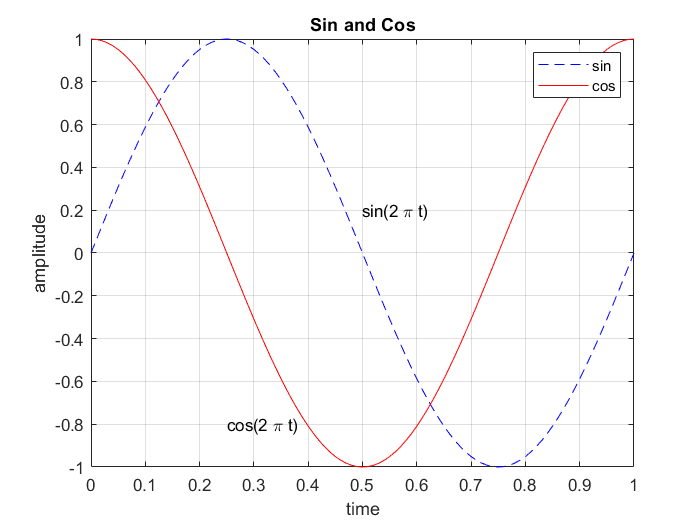

t = 0:0.01:1;
z1 = sin(2*pi*t);
z2 = cos(2*pi*t);

figure;
plot(t, z1, '--b')
hold on
plot(t, z2, 'r')

x0 = [0.5;0.25];
y0 = [0.2;-0.8];
s = ["sin(2 \pi t)"; "cos(2 \pi t)"];
text(x0, y0, s);
title('Sin and Cos');
legend('sin', "cos")
xlabel('time')
ylabel('amplitude')
grid on

The code below is the same code but *hold on *command is commented.

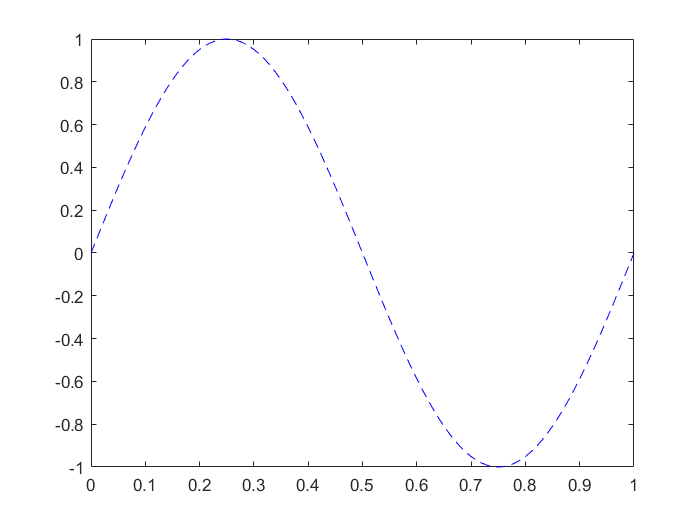

figure;
plot(t, z1, '--b')

%hold on
plot(t, z2, 'r')

x0 = [0.5;0.25];
y0 = [0.2;-0.8];
s = ["sin(2 \pi t)"; "cos(2 \pi t)"];
text(x0, y0, s);
title('Sin and Cos');
legend('sin', "cos")

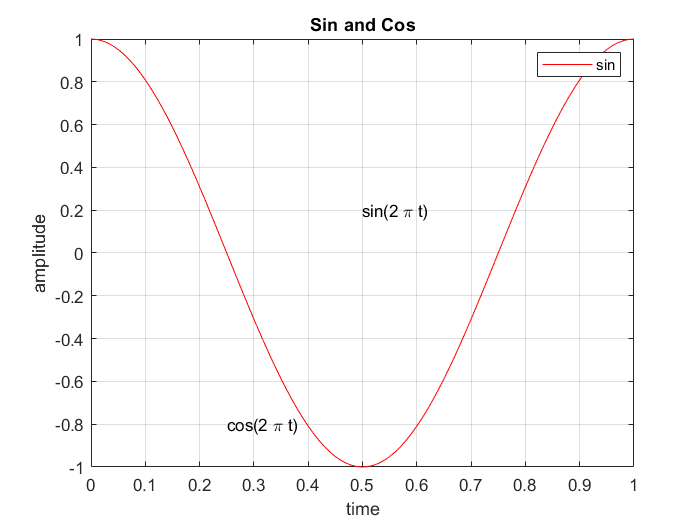

xlabel('time')
ylabel('amplitude')
grid on

#### 1-2

    In this part, We are asked to plot each function on a subplot in one figure instead of plotting them on the same plot. Using *subplot *command we implement this. subplot takes three arguments: m, n and p. m and n says how many rows and columns our figure has and p is the number of the current suplot we are working on. The rest is like the last part.

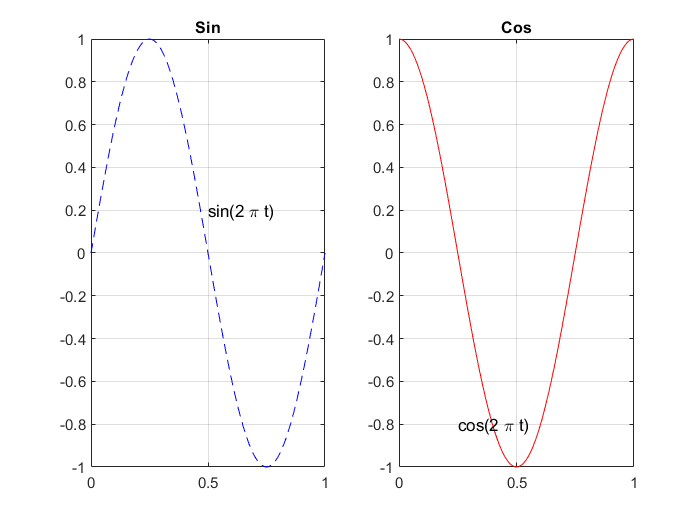

subplot(1,2,1)
t = 0:0.01:1;
z1 = sin(2*pi*t);
plot(t, z1, '--b')
text(x0(1), y0(1), s(1));
title('Sin')
grid on

subplot(1, 2, 2)
z2 = cos(2*pi*t);
plot(t, z2, 'r')
text(x0(2), y0(2), s(2));
title('Cos')
grid on

### Part Two

#### 2-1 and 2-2

    In this part we have a system shown below:

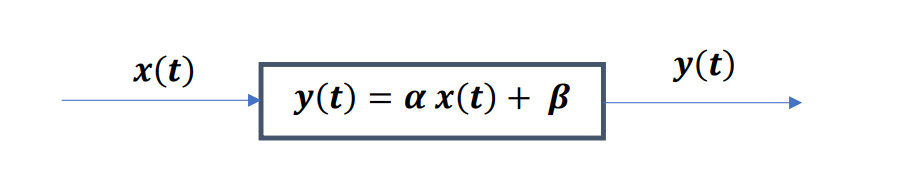

    In "p2.mat" file, values for $$x(t)$$and $y\left(t\right)$ are stored. So we load and plot them.

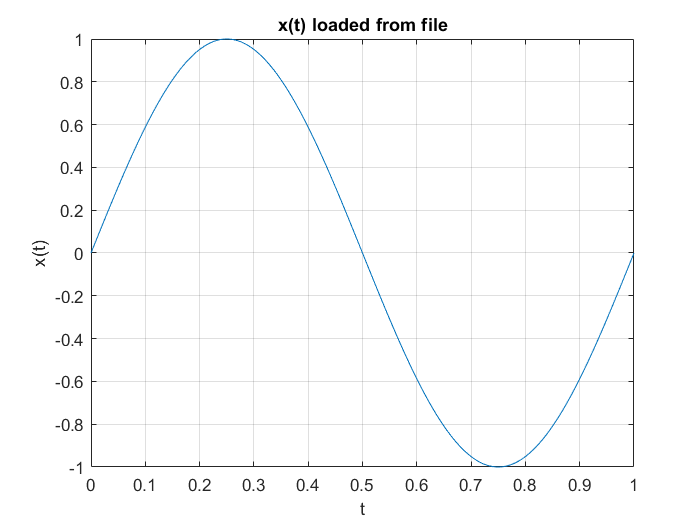

figure;
load("p2.mat", "t", "x", "y")
plot(t, x)
title("x(t) loaded from file")
ylabel("x(t)")
xlabel("t")
grid on

As you can see, y(t) is noisy which is natural in real world examples and we can't always expect clean data.

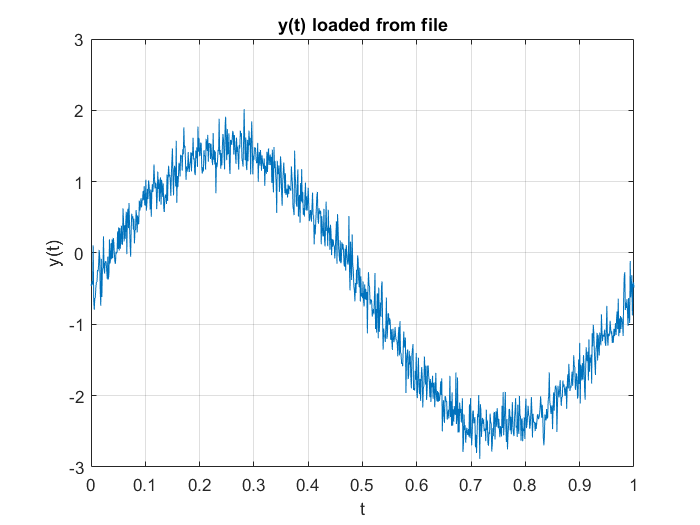

plot(t, y)
title("y(t) loaded from file")
ylabel("y(t)")
xlabel("t")
grid on

#### 2-3

    Now we plot y as a function of x to see their relation. As you can see, y and x seems to have a linear relation which makes sense(we already know what the system is doing!). 

**    What does the slope and y intercept of the plot tell us?**

- slope of this plot is $\alpha$ in the system's equation and the y intercept is $\beta \ldotp$

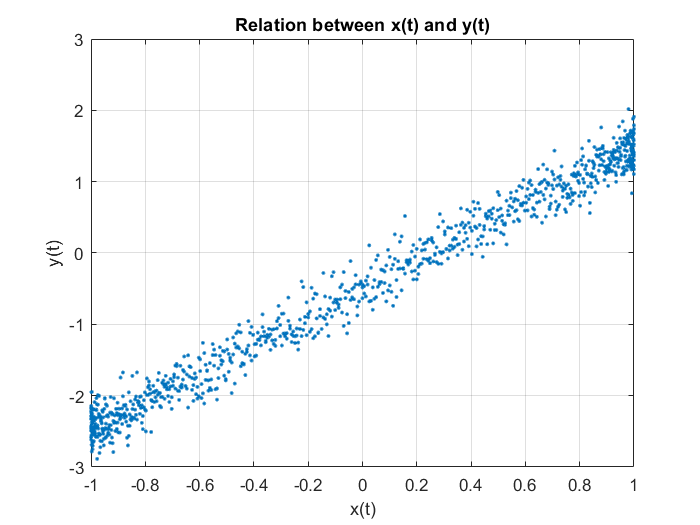

plot(x, y, '.');
title("Relation between x(t) and y(t)")
ylabel("y(t)")
xlabel("x(t)")
grid on

#### 2-4

    Now in order to find $\alpha \;$and $\beta$, we have to find the best line that fits this data. In other words we have to minimize this loss function:

###     
$$f\left(\alpha ,\beta \right)=\;\sum_t {\left(y\left(t\right)-\alpha x\left(t\right)-\beta \right)}^2 \;$$


by getting partial derivative, we can find the best values for $\alpha$ and $\beta$.

#### 
$$\frac{\partial }{\partial \beta }f=2\sum_t \left(-y\left(t\right)+\beta +\alpha \ldotp x\left(t\right)\right)=0$$

$$\Rightarrow \beta =\bar{y} -\alpha \bar{x}$$


where $\bar{x}$ means the mean of array $x$ and $\bar{y}$ is mean of array$\;y$.

For $\alpha :$

####                         $\frac{\partial }{\partial \alpha }f$ = $2\sum_t \left(-x\left(t\right)\ldotp y\left(t\right)+\beta \ldotp x\left(t\right)+\alpha \ldotp {x\left(t\right)}^2 \right)=0$  

using the equation we derived for $\beta :$

#### 
$$\alpha =\frac{\sum_t \left(x\left(t\right)-\bar{x} \right)\left(y\left(t\right)-\bar{y} \right)}{\sum_t {\left(x\left(t\right)-\bar{x} \right)}^2 }$$


So we can calculate $\alpha$ and $\beta$ easily using these equations.

We write a function that takes x and y and gives the coefficients of the best line that fits the data.(The function can be seen at end of the report).

coeff = one_degree_regression(x, y);

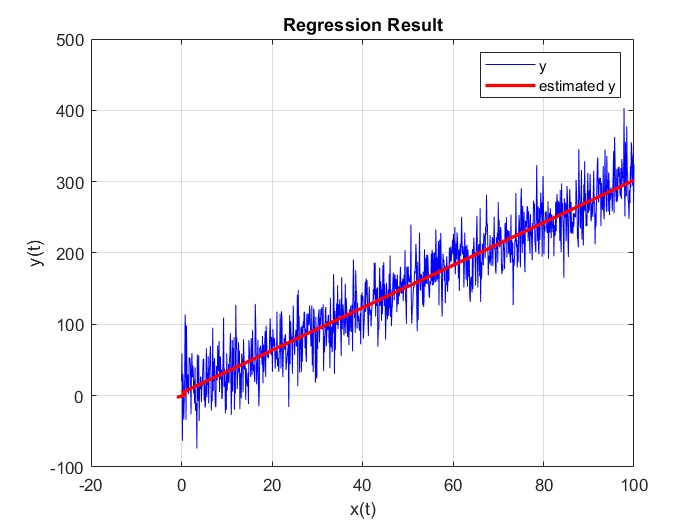

alpha = coeff(1);
beta = coeff(2);
y_hat = alpha * x + beta;
plot(x, y, '-b')
hold on

plot(x, y_hat, '-r', 'LineWidth', 2)
title("Regression Result")
ylabel("y(t)")
xlabel("x(t)")
legend(["y";"estimated y"])
grid on

fprintf("alpha is %f and beta is %f", alpha, beta);

alpha is 1.973579 and beta is -0.498339

Now in order to test our method, we make a new data and add some noise to it:

#### 
$$y\left(t\right)=3\ldotp x\left(t\right)+4+\textrm{noise}$$


Noise is a random value from normal distribution.

As you can see, this method works with this data too.

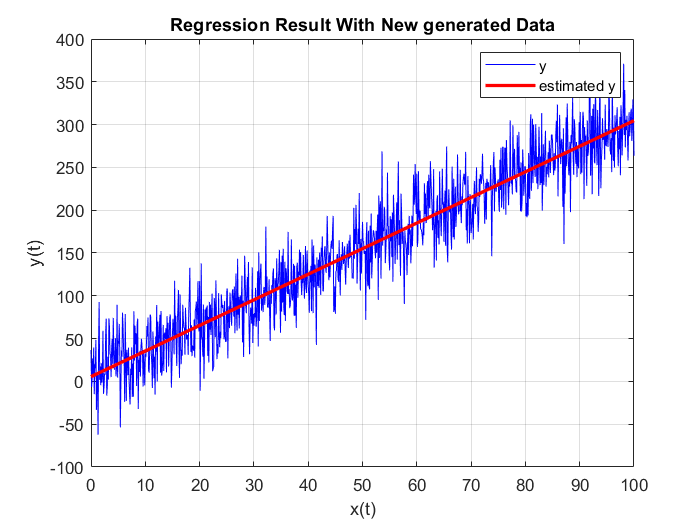

figure;
x_test = 0:0.1:100;
noise = 30 * randn(1, 1001);
y_test = 3 * x_test + 4 + noise;

coeff_test = one_degree_regression(x_test, y_test);
alpha_test = coeff_test(1);
beta_test = coeff_test(2);
y_hat_test = alpha_test * x_test + beta_test;

plot(x_test, y_test, '-b')
hold on
plot(x_test, y_hat_test, '-r', 'LineWidth', 2)
title("Regression Result With New generated Data")
ylabel("y(t)")
xlabel("x(t)")
legend(["y";"estimated y"])
grid on

fprintf("alpha is %f and beta is %f", alpha_test, beta_test);

alpha is 2.990481 and beta is 5.573777

#### 2-5

    We can also use MATLAB's Curve Fitting tool to estimate this data with a line:

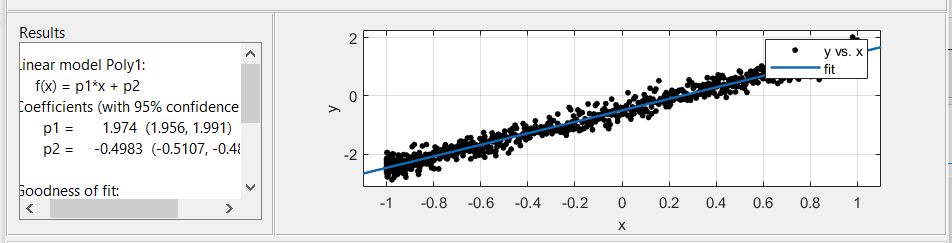

As you can see the coefficients are equal to our method.

### Part Three

#### 3-1

    In this part we want to determine the distance from an object by sending a wave towards it and calculating the delay between the sent wave and received wave.

First we initialize and plot the wave we sent towards the object: The wave is a square signal with $\tau ={10}^{--6}$ and Sample rate is ${10}^{-9}$

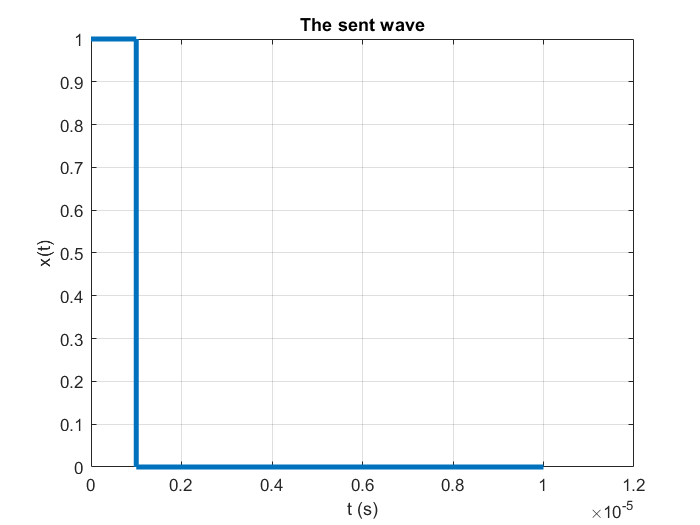

ts = 1e-9;
T = 1e-5;
tau = 1e-6;

t = 0:ts:T;
x_sent = zeros(size(t));
N = round(tau / ts);
x_sent(1:N) = 1;
figure;
plot(t, x_sent, 'LineWidth', 3);
title("The sent wave")
ylabel("x(t)")
xlabel("t (s)")
grid on

#### 3-2

Now we plot the wave that we recieve. We assume that the distance is 450 and the wave is weakened by $\alpha =0\ldotp 5$. We use the equation below to determine the delay time of this wave.

### 
$$t_d =\frac{2R}{c}$$


where $c$ is the speed of light.

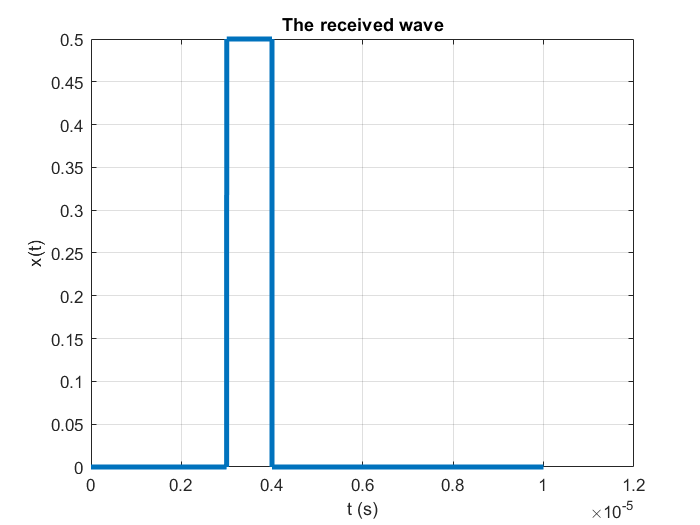


alpha = 0.5;
R = 450;
C = 3e8;
td = 2 * R / C;
td_index = round(td / ts);
x_received = zeros(size(t));
x_received(td_index : td_index + N) = alpha;
plot(t, x_received, 'LineWidth', 3);
title("The received wave")
ylabel("x(t)")
xlabel("t (s)")
grid on

#### 3-3

Now we want to determine the distance. We use template matching which is simply the dot product of a segment of the recieved wave and an array of 1.

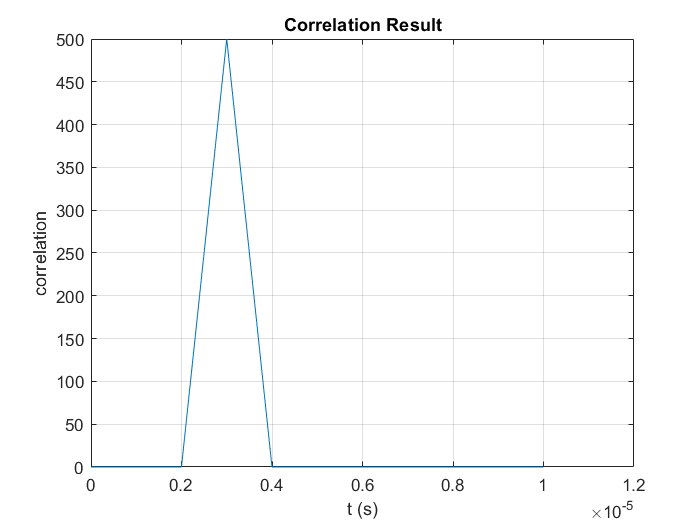

correlation = zeros(size(t));
tlen = length(t);
for i = 1 : tlen - N
    cur_segment = zeros(1, tlen);
    cur_segment(i : i +N - 1) = 1;
    correlation(i) = innerproduct(cur_segment , x_received);
end
plot(t, correlation);
title("Correlation Result")
ylabel("correlation")
xlabel("t (s)")
grid on

In correlation result, Where we have a peak is the delay time of the recieved wave. So now that we have $t_d$ we can easily figure out what $R$ is.

[mx_cor, td_derived] = max(correlation);
td_derived = td_derived * ts;
R_derived = C * td_derived / 2;
fprintf("distance is %d", R);

distance is 450

#### 3-4

    In this part we want to see how our method works when our data has some noise. For each noise power we calculate the error 100 times and in the end plot the average error for each noise power. You can see the *innerproduct* function at the end of the file. As expected the more the noise power, the more error we have. We assume that errors less than 10 m is considered to be a good estimation, so our method doesn't work well for noise power $\ge$ 3.3.                                                                                                                                                                                                                                                   

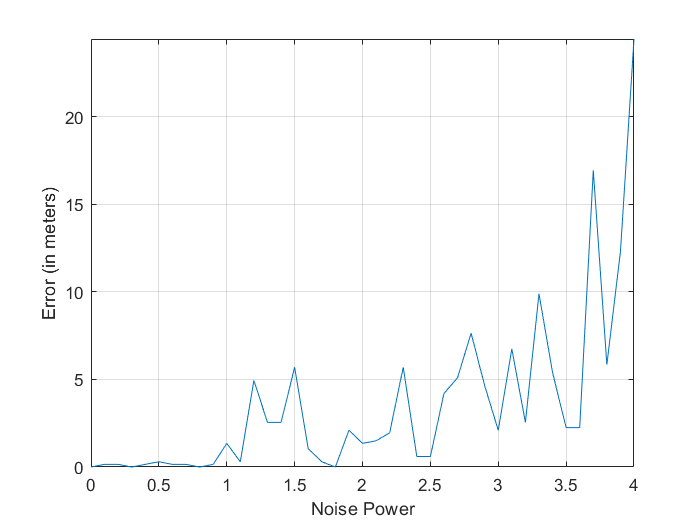

noise_power = 0:0.1:4;
ITERATION_NUM = 100;
errors = zeros(size(noise_power));
for i = 1 : length(noise_power)
    cur_noise_power = noise_power(i);
    cur_noise = cur_noise_power * randn(1, tlen);
    x_recieved_noise = x_received + cur_noise;
    err = 0;
    for j = 1 : ITERATION_NUM
        cor = calc_correlation(t, x_recieved_noise, N);
        [mx_cor, td_derived] = max(cor);
        td_derived = td_derived * ts;
        R_derived = C * td_derived / 2;
        err = err + abs(R_derived - R);
    end
    err = err / ITERATION_NUM;
    errors(i) = err;
end
plot(noise_power, errors)
xlabel("Noise Power")
ylabel("Error (in meters)")
ylim([0, max(errors)])
grid on

### Part Four

#### 4-1 and 4-2

    In this part we are working with sound data. First we load our audio file. The outputs are the array consisting of audio data and the sample frequency(per second) of the audio file. We also plot the audio array. Then we play the audio and save it in another file.(*new_audio.wav*)

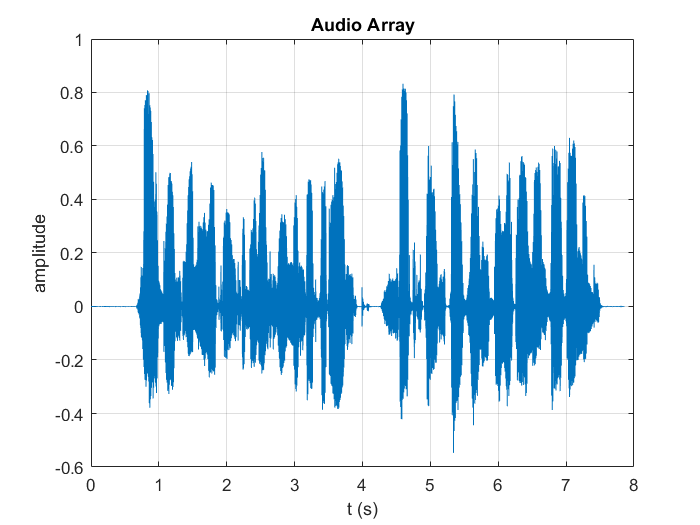

[audio, Fs] = audioread('hafez.wav');
t = (0 : length(audio) - 1) / Fs;
plot(t, audio);
title("Audio Array")
ylabel("amplitude")
xlabel("t (s)")
grid on

audiowrite("new_audio.wav", audio, Fs);
sound(audio, Fs);

#### 4-3

    Now we want to write a function that gets the audio array and a speed(which can be only 0.5 or 2), then play the audio with given speed. For speed = 2, We only take even indices and for speed = 2, We add a new value between every two value. The new value is the average of those two current values. We implement this method in *play_audio *function which can be seen at the end of the file.

#### speed = 0.5:

play_audio(audio, Fs, 0.5);

#### speed = 2

play_audio(audio, Fs, 2);

#### Invalid speed

play_audio(audio, Fs, 1.1);

speed must be 0.5 or 2

#### 3-4

    We can also improve the function to accept every speed between 0.5 and 2. The way we implement it is by finding the coresponding index in the original audio. For example if the new audio is 1.2 times bigger than the original, for each index we divide it by 1.2 to find the coresponding index in the original audio and then set its value for the new audio.(I set the average of the ceil and floor of the corespnding index):

###     
$${\textrm{newAudio}}_i =\frac{{\textrm{Audio}}_{\left\lceil i*\textrm{speed}\right\rceil } +{\textrm{Audio}}_{\left\lfloor i*\textrm{speed}\right\rfloor } }{2}$$


The *play_audio_improved*  function can be seen at the end of the file. 

play_audio_improved(audio, Fs, 1.4)

### Functions

function coeff = one_degree_regression(x, y) 
    alpha = sum((x - mean(x)).*(y - mean(y))) / sum((x - mean(x)).^2);
    beta = mean(y) - alpha * mean(x);
    coeff = [alpha; beta];
end


function ro = innerproduct(x, y)
    ro = sum(x.*y);
end

function cor = calc_correlation(t, x, N)
    cor = zeros(size(t));
    tlen = length(t);
    for i = 1 : tlen - N
        cur_segment = zeros(1, tlen);
        cur_segment(i : i +N - 1) = 1;
        cor(i) = innerproduct(cur_segment , x);
    end
end

function play_audio(audio, Fs, speed)

    if speed ~= 2 && speed ~= 0.5
        error("speed must be 0.5 or 2");
    end
    
    if speed == 2
        new_audio = audio(2:2:end);
        
    elseif speed == 0.5
        new_audio = zeros(1, length(audio) * 2);
        new_audio(1) = audio(1);
        for i = 2 : length(new_audio)
            new_audio(i) = (audio(ceil((i) / 2)) + audio(floor((i) / 2))) / 2;
        end
    end
    
    sound(new_audio, Fs);
    
end

function play_audio_improved(audio, Fs, speed)
    if (speed >= 2 && speed <= 0.5 || speed * 10 ~= round(speed * 10))
        error("speed should be between 0.5 and 2. speed should be multiple of 0.1.");
    end
    new_audio = zeros(1, floor(length(audio) / speed));
    new_audio(1) = audio(1);
    for i = 2 : length(new_audio)
        new_audio(i) = (audio(ceil(i * speed)) + audio(floor(i * speed))) / 2;
    end
    sound(new_audio, Fs);
    
    
end

